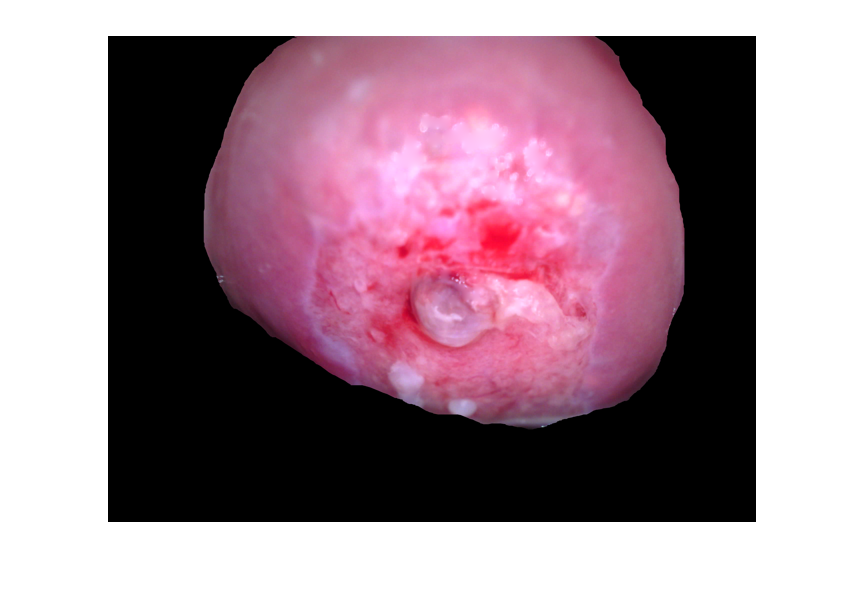

%read and display input image
A = W26_2;%imread('W60.tif');
A = imresize(A,0.25);
Agray = rgb2gray(A);
figure
imshow(A)

%% Design gabor filter array
imageSize = size(A);
numRows = imageSize(1);
numCols = imageSize(2);

wavelengthMin = 4/sqrt(2);
wavelengthMax = hypot(numRows,numCols);
n = floor(log2(wavelengthMax/wavelengthMin));
wavelength = 2.^(0:(n-2)) * wavelengthMin;

deltaTheta = 45;
orientation = 0:deltaTheta:(180-deltaTheta);

g = gabor(wavelength,orientation);

gabormag = imgaborfilt(Agray,g); %magnitude features



%% Post processing, gaussian filter
 for i = 1:length(g)
    sigma = 0.5*g(i).Wavelength;
    K = 3;
    gabormag(:,:,i) = imgaussfilt(gabormag(:,:,i),K*sigma); 
 end
 
 


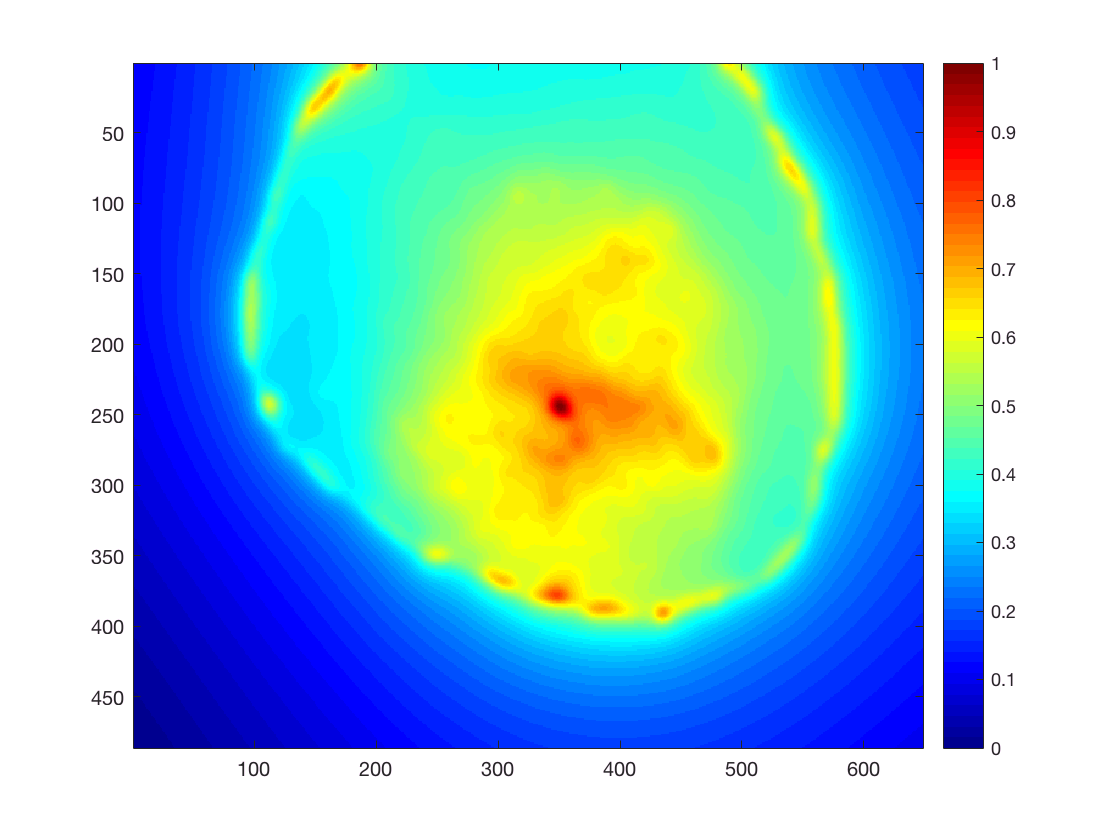


X = 1:numCols;
Y = 1:numRows;
[X,Y] = meshgrid(X,Y);
featureSet = cat(3,gabormag,X);
featureSet = cat(3,featureSet,Y);

numPoints = numRows*numCols;
X = reshape(featureSet,numRows*numCols,[]);

X = bsxfun(@minus, X, mean(X));
X = bsxfun(@rdivide,X,std(X));

coeff = pca(X);
feature2DImage = reshape(X*coeff(:,1),numRows,numCols);
f=feature2DImage ;
norm_feat=(f-min(min(f)))./(max(max(f))-min(min(f)));
figure
imagesc(norm_feat);colormap('jet');colorbar;caxis([0,1])

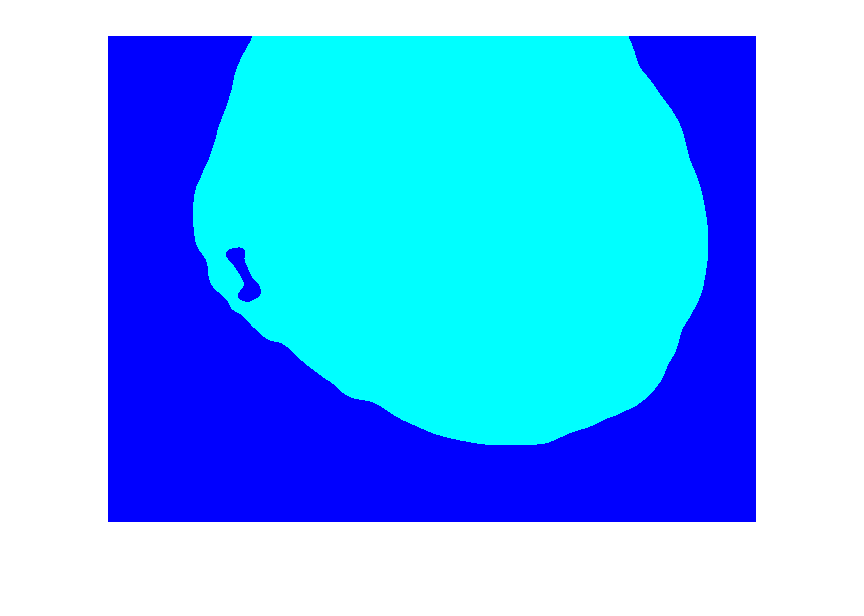


%% Classify gabor texture using k means with k=2

L = kmeans(X,2,'Replicates',5);

L = reshape(L,[numRows numCols]);
figure
imshow(label2rgb(L))

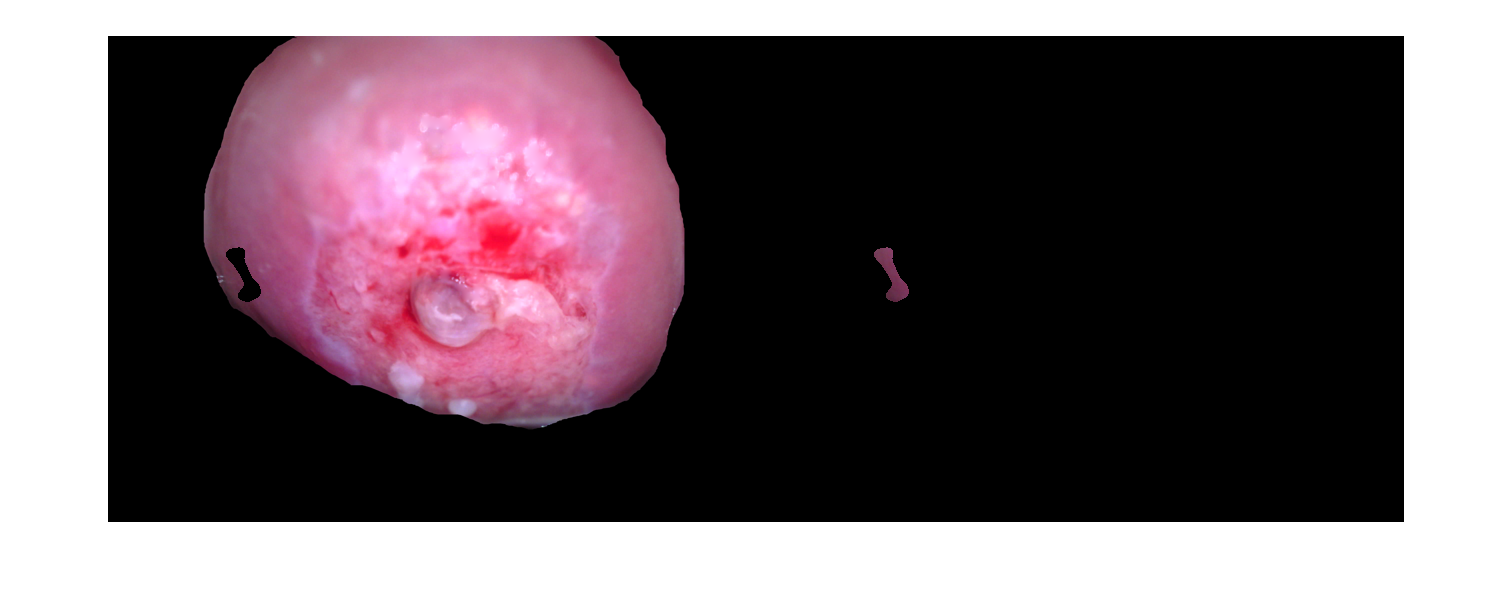


Aseg1 = zeros(size(A),'like',A);
Aseg2 = zeros(size(A),'like',A);
BW = L == 2;
BW = repmat(BW,[1 1 3]);
Aseg1(BW) = A(BW);
Aseg2(~BW) = A(~BW);
figure
imshowpair(Aseg1,Aseg2,'montage');